%{
ES115 Engineering Computer Applications
Module 9 Project: Cooling Curve Approximation

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project models how temperature changes over time during a cooling
process. Given discrete temperature data, the goal is to visualize the
cooling curve, estimate the rate of temperature change, and calculate
the total thermal exposure using numerical methods.

Inputs (Knowns):
- Time values (t) from 0 to 20 minutes in steps of 2
- Temperature data (T) corresponding to each time value
- Time step (Δt) = 2 minutes

Outputs (Unknowns):
- Graph of temperature vs time (cooling curve)
- Rate of change of temperature over time
- Graph of rate of change vs time
- Estimated total thermal exposure (area under the curve)

Engineering Workflow and Algorithms:
- Define time and temperature data
- Plot temperature vs time
- Use finite difference method to estimate rate of change (dT/dt)
- Adjust time values for derivative data
- Plot rate of change vs time
- Use numerical integration (trapezoidal rule) to estimate total area

MATLAB Tools / Functions Used:
- plot() for graphing
- diff() for numerical differentiation
- trapz() for numerical integration
- indexing to align time and derivative values
- fprintf() for displaying results

Reflection After Completing the Project:
- I learned how to analyze real-world data using numerical methods like
  finite differences and trapezoidal integration.
- I also understood how temperature changes over time and how to estimate
  rates of change from discrete data.
- If I were to improve this, I would use a smoother model or curve fitting
  to better represent the cooling process.
- Difficulty Rating: 5/10 — understanding the numerical methods took some
  effort, but applying them in MATLAB was manageable.
%}



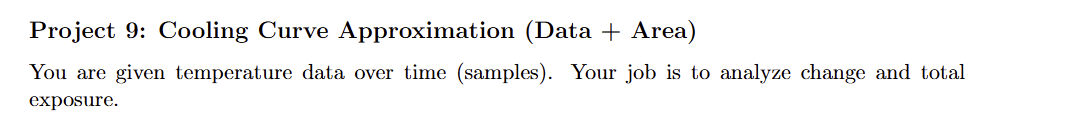

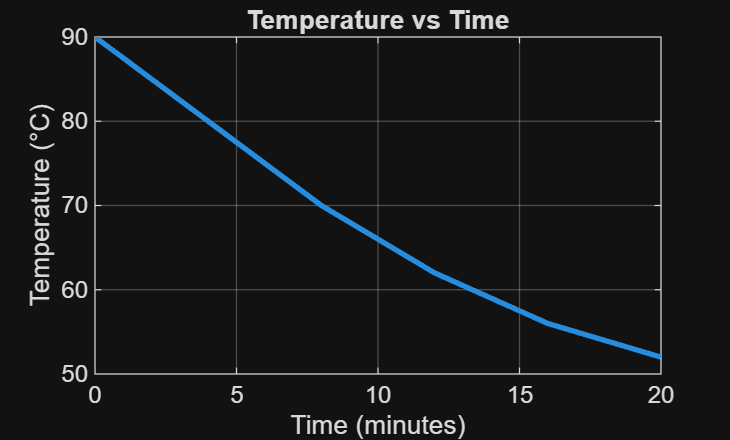

 
clear; clc; close all; 
 
% ---------------------------- 
% Time vector (minutes) 
t = 0:2:20; 
 
% ---------------------------- 
% Temperature data (decreasing) 
T = [90 85 80 75 70 66 62 59 56 54 52]; 
 
% ---------------------------- 
% Plot temperature vs time 
figure; 
plot(t, T, 'LineWidth', 2); 
 
title('Temperature vs Time'); 
xlabel('Time (minutes)'); 
ylabel('Temperature (°C)'); 
grid on; 

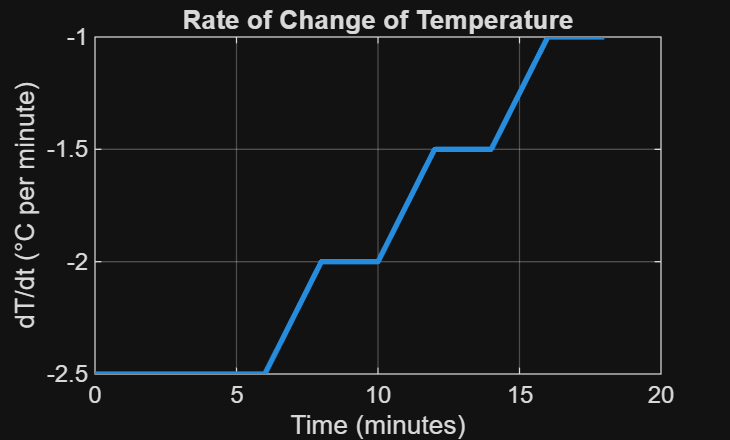

 
% ---------------------------- 
% Rate of change (finite differences) 
dt = 2; 
dT = diff(T) / dt; 
 
% Adjust time for derivative 
t_rate = t(1:end-1); 
 
% Plot rate of change 
figure; 
plot(t_rate, dT, 'LineWidth', 2); 
 
title('Rate of Change of Temperature'); 
xlabel('Time (minutes)'); 
ylabel('dT/dt (°C per minute)'); 
grid on; 

 
% ---------------------------- 
% Total thermal exposure (area under curve) 
area = trapz(t, T); 
 
fprintf('Estimated total thermal exposure: %.2f\n', area); 

Estimated total thermal exposure: 1356.00
